# ***Invisible watermarking for digital images***

## ***Generating the input image DCT***

Let's start with an un-watermarked image.

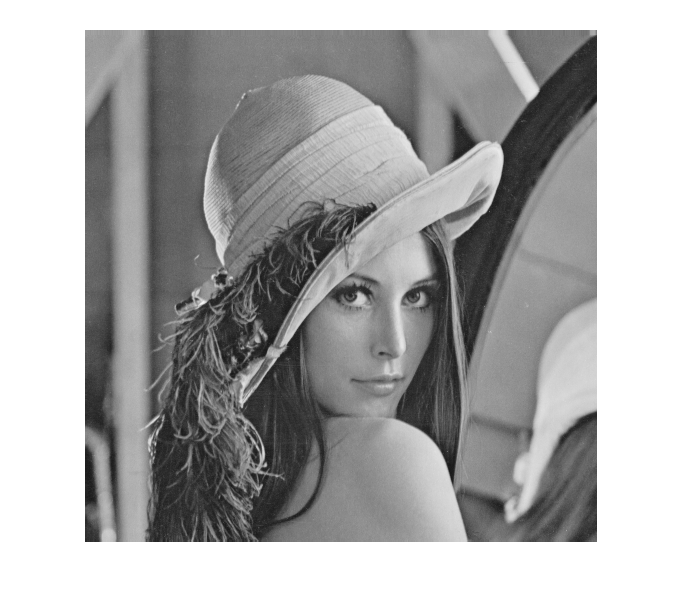

im = imread('lena.tiff');
figure, imshow(im)

We'll apply a quantization matrix for compression. The standard quantization matrix is

QP = [16  11  10  16  24  40  51  61;
      12  12  14  19  26  58  60  55;
      14  13  16  24  40  57  69  56;
      14  17  22  29  51  87  80  62;
      18  22  37  56  68 109 103  77;
      24  35  55  64  81 104 113  92;
      49  64  78  87 103 121 120 101;
      72  92  95  98 112 100 103  99];
  

Then find the DCT as per normal.

im_dct = blockproc(double(im), [8 8], @(b) round(dct2(b.data)));

Scale the values by the (scaled) quantization matrix.

scale_f = 0.5;
QP_scale = QP .* scale_f;
quant_dct= @(block_struct) round(block_struct.data ./ QP_scale) .* QP_scale;
im_quant = blockproc(im_dct, [8 8], quant_dct);

## Adding the watermark to the DCT

The watermark will be a string of characters. Each character will be encoded as a digit 0->26 corresponding to its frequency in the english alphabet, as well as numbers 0 to 9.

letter_freq = {' ', 'e', 't', 'a', 'o', 'i', 'n', 's', 'h', 'r', 'd', 'l', 'c', ...
               'u', 'm', 'w', 'f', 'g', 'y', 'p', 'b', 'v', 'k', 'j', 'x', 'q', ...
               'z', '1', '2', '3', '4', '5', '6', '7', '8', '9', '0'};
letter_offsets = containers.Map(letter_freq, [0:length(letter_freq)-1]);

% Matlab doesn't have a nice way to do reverse-lookup in a map so we'll make a dual map
offset_letters = containers.Map(values(letter_offsets), keys(letter_offsets));

Now we can convert our watermark phrase into a set of minimal offsets.

wm = 'Hello ELEC 483!';
wm = lower(wm);

offsets = zeros(size(wm));
for i = 1:length(wm)
    if letter_offsets.isKey(wm(i))
        offsets(i) = letter_offsets(wm(i));
    else
        offsets(i) = 0;
    end
end

Determine the set of coordinates that correspond to the top-left corner of each DCT block.

[Xs Ys] = meshgrid([1:8:size(im_quant,1)], [1:8:size(im_quant,2)]);
corners = [Xs(:) Ys(:)];

corners =      1     1
     1     9
     1    17
     1    25
     1    33
     1    41
     1    49
     1    57
     1    65
     1    73


Now add the encoded character value to each block.

% In actual encoding we'd add values to im_quant before exporting.
% For demo purposes we'll copy im_quant so it can be re-used in decoding.
im_wm = im_quant;

for i = 1:length(offsets)
    coord = corners(i,:);
    x = coord(1,1); y = coord(1,2);
    im_wm(x,y) = im_wm(x,y) + offsets(1,i);
end

## Retrieving the watermark

Subtract the original image from the watermarked image to retrieve the added watermark coefficients. Then extract the offsets from the corners.

diff = im_wm - im_quant;

wm_offsets = zeros(1, length(corners));
for i = 1:length(corners)
    coord = corners(i,:);
    x = coord(1,1); y = coord(1,2);
    wm_offsets(1,i) = diff(x,y);
end

Reconstruct the phrase by running the sets through the inverse map.

phrase = '';
for i = 1:length(wm_offsets)
    offset = wm_offsets(1,i);
    if offset_letters.isKey(offset)
        phrase = strcat(phrase, offset_letters(offset));
    end
end
phrase

phrase = helloelec483

## Image quality comparison

Since we add values to the DCT coefficient we should expect a lower PSNR for the watermarked image.

First we'll examine the un-modified image.

im_r = blockproc(im_quant, [8 8], @(b) idct2(b.data));
psnr = 10 * log10(255 * 255 / mean(mean((double(im) - im_r).^2)))

psnr = 37.8818

And then the watermarked image.

im_wm_r = blockproc(im_wm, [8 8], @(b) idct2(b.data));
psnr_wm = 10 * log10(255 * 255 / mean(mean((double(im) - im_wm_r).^2)))

psnr_wm = 37.8767

The difference is

psnr - psnr_wm

ans = 0.0051

The watermarked image looks identical to the unwatermarked image.

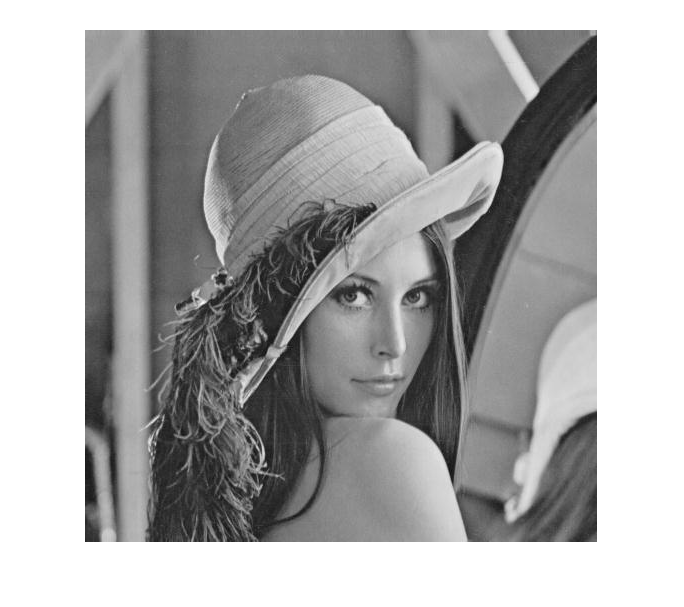

figure, imshow(uint8(im_wm_r))